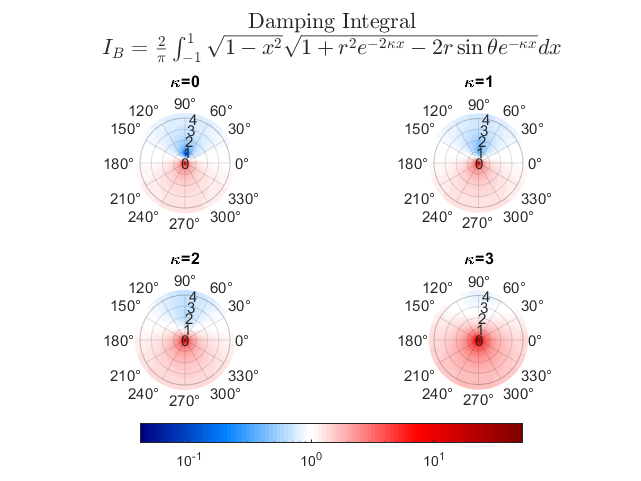

clear
r_primve_vec = linspace(.05,4,40);
r_vec = 1./r_primve_vec;
theta_vec = 0:pi/48:2*pi;
kappa_vec = 0:3;
[R,TH,K] = meshgrid(r_vec,theta_vec,kappa_vec);

[B, G_real, G_imag] = compute_drag_integral(R,TH,K);

G = G_real + 1i * G_imag;
G_mag = abs(G);
G_phase = angle(G);

int_sign = '\int_{-1}^1';
basic_integrand = '\sqrt{1-x^2}\sqrt{1+r^2e^{-2\kappa x}-2r\sin\theta e^{-\kappa x}}';

B_label = 'Damping Integral';
Gr_label = 'Real Excitation Integral';
Gi_label = 'Imaginary Excitation Integral';
Gm_label = 'Magnitude Excitation Integral';
Gp_label = 'Phase Excitation Integral';

B_math  = ['$I_B=\frac{2}{\pi}'                int_sign, basic_integrand                '  dx$'];
Gr_math = ['$\Re(I_{G})=\frac{2}{\pi}'         int_sign, basic_integrand '\cos(-\kappa x)  dx$'];
Gi_math = ['$\Im(I_{G})=\frac{2}{\pi}'         int_sign, basic_integrand '\sin(-\kappa x)  dx$'];
Gm_math = ['$|I_{G}|=\frac{2}{\pi}\left|'      int_sign, basic_integrand 'e^{-i\kappa x}   dx \right|$'];
Gp_math = ['$\angle I_{G}=\frac{1}{\pi}\angle' int_sign, basic_integrand 'e^{-i\kappa x}   dx $'];

fig_B   = integral_plot(R,TH,kappa_vec, 2/pi*B,          {B_label, B_math}, 1);

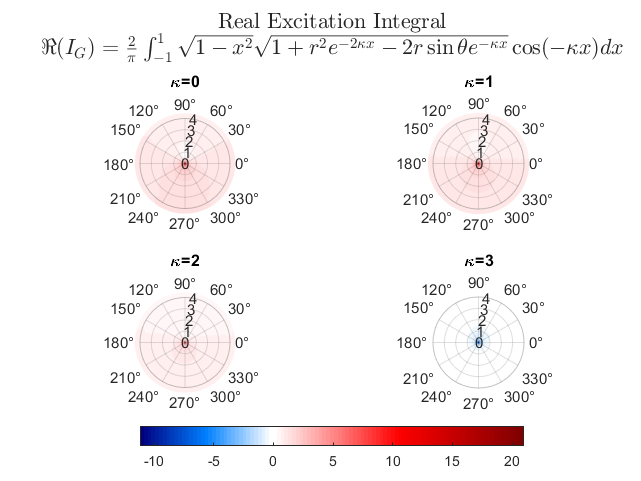

fig_G_r = integral_plot(R,TH,kappa_vec, 2/pi*G_real,     {Gr_label,Gr_math}, 0);

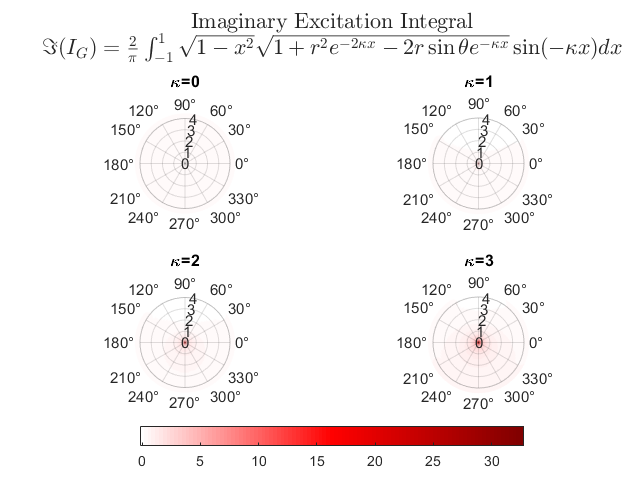

fig_G_i = integral_plot(R,TH,kappa_vec, 2/pi*G_imag,     {Gi_label,Gi_math}, 0);

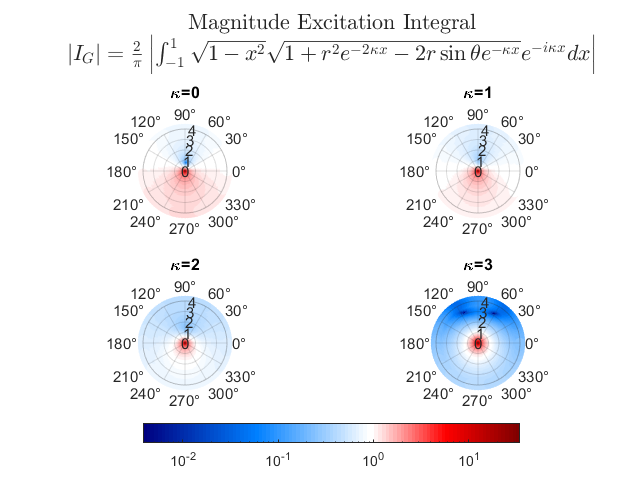

fig_G_m = integral_plot(R,TH,kappa_vec, 2/pi*G_mag,      {Gm_label,Gm_math}, 1);

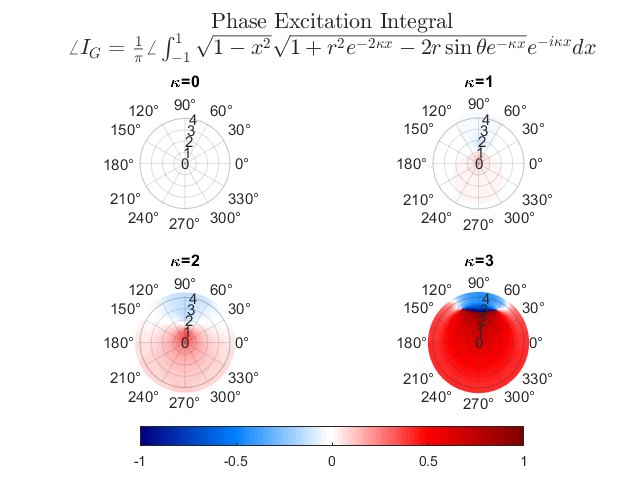

fig_G_p = integral_plot(R,TH,kappa_vec, 1/pi*G_phase,{Gp_label,Gp_math}, 0);
clim([-1 1])

function fig = integral_plot(R,TH,kappa_vec,T,mytitle,white_val_in)
fig = figure;
t = tiledlayout(2,2);
for i=1:length(kappa_vec)
    r_prime = 1./R(:,:,i);
    theta = TH(:,:,i);
    
    use_logscale = all(T(:)>0);
    
    if use_logscale
        all_val = log(T(:));
        val = log(T(:,:,i));
        white_val = log(white_val_in);
    else
        all_val = T(:);
        val = T(:,:,i);
        white_val = white_val_in;
    end
    min_max = [min(all_val), max(all_val)];
    if use_logscale
        val_lims = exp(min_max);
    else
        val_lims = min_max;
    end

    nexttile(t)

    val_0_1 = ( val - min(all_val) ) / (max(all_val) - min(all_val)); % continuous 0 to 1
    val_0_100 = round(val_0_1*100); % integer 0 to 100
    whiteval_0_1 = (white_val-min(all_val)) / (max(all_val) - min(all_val));
    whiteval_0_100 = round(whiteval_0_1 * 100);
    colmap = colormap(bluewhitered(101,whiteval_0_100,[1,100])); % indexed by integer 1 to 101
    color = colmap(val_0_100+1,:);
    sz = r_prime(:)*10;

    polarscatter(theta(:), r_prime(:), sz, color, 'filled');
    colormap(colmap)
    clim(val_lims)
    if use_logscale
        set(gca,'colorscale','log')
    end

    title( ['\kappa=' num2str(kappa_vec(i))] )
    ax = gca;
    ax.Layer = 'top';
end
cb = colorbar;
cb.Layout.Tile = 'south';
title(t,mytitle,'Interpreter','latex')
end